# Aula 4 - Laboratório de Controle - 2023/1											

## Sistemas discretos: discretização e estabilidade 						

## Nome(s): (coloque os nomes aqui)

I=0; % Use seu valor de I
u0=init4(I)
datetime('now')

Nesta aula os modelos são estimados a partir da coleta de dados do circuito RC conectado ao Arduino. Os modelos contínuos serão discretizados e analisados em malha aberta e malha fechada. A figura abaixo mostra as conexões usadas para esta aula.

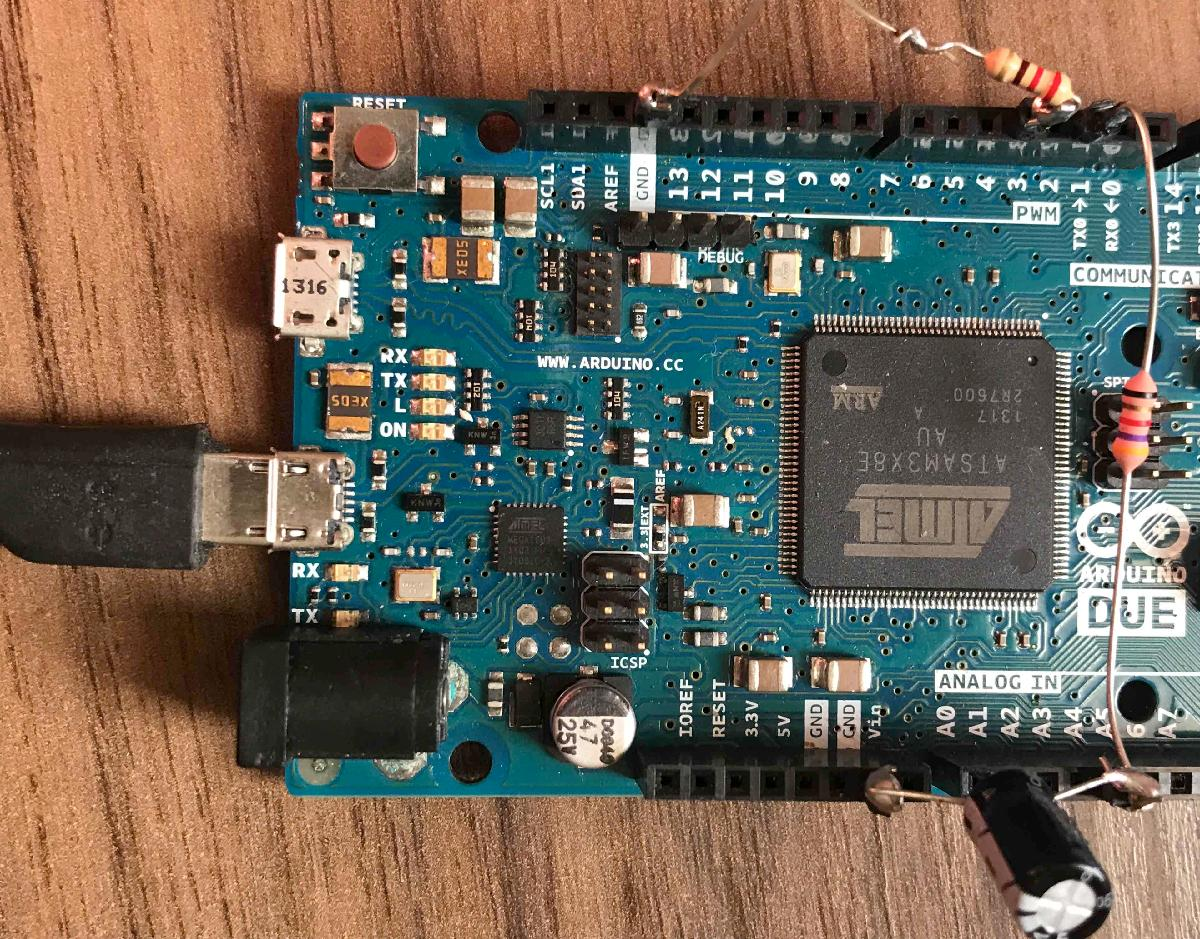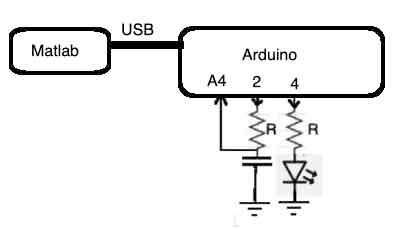

## Atividade 1 - Obtenção de um modelo contínuo e discreto para o circuito RC 

Nesta aula, os modelos serão obtidos com a função procest, que usa os dados coletados pelo Arduino e estima os parâmetros do modelo desejado. Isso substitui a tarefa da aula 3 de obter a constante de tempo e o ganho a partir da curva de resposta ao degrau. Permite também obter modelos mais complexos.

Para maiores informações sobre esta função, que será bastante utilizada, dê o comando help procest.

Inicialização da comunicação do Matlab com Arduino:

if ~exist('obj')
    z=seriallist;
    comPort=z{length(z)};
    obj=serial(comPort,'BaudRate',9600);
    obj.Terminator='CR';
    fopen(obj);
end

Os comandos a seguir fazem a coleta dos dados do circuito RC após a aplicação do degrau com amplitude u0.

Tempo=0; % Escolher o tempo adequado para a visualizacao da resposta transitoria e de regime
U0=[ 0 u0]; % u0 vem de init4
[y,t]=arduino_coleta_rc(obj,0,Tempo); % zerar saida 
[y,t]=arduino_coleta_rc(obj,U0,Tempo);
figure
stairs(t,y);
ss=sprintf('Fig.1: Resposta para o degrau de amplitude u0=%d aplicado',u0);
title(ss);
seta_saida_rc(obj,0);

Estimação de um modelo de ordem 1 sem atraso com a função procest.

`sys = procest(data,type)`

`sys: modelo estimado`

`data: dados de entrada e saída estruturados com o comando iddata`

`type: modelo desejado`

Ts=20; % Tempo de amostragem fixo em ms
N=floor(length(y)/2);
L=floor(N-10); 
y0=mean(y(L-1:L));
yf=mean(y(end-5:end));
yn=y(L:end)-y0;
u=[zeros(size(y(L:N+1)));ones(N-1,1)*(U0(2)-U0(1))];
t=(0:length(yn)-1)*Ts/1000;
data=iddata(yn,u,Ts/1000); % Dados usados para obter o modelo
g1=procest(data,'P1'); % Função para estimar o modelo de ordem 1
G1=tf(g1.Kp,[g1.Tp1 1])


Avaliação do modelo usando a métrica fit: $fit=100(1-\frac{||y-\hat{y}||)}{||y-\bar{y}|| $, sendo $\hat{y}$ a saída estimada pelo modelo, $y$ a saída coletada e $||y||$ o valor médio de $y$. 

O modelo ótimo (sem erro) tem$fit=100\%$.

figure;
compare(data,g1); % Avaliacao do modelo
title('Figura 2. Comparação da resposta do modelo de ordem 1 com os dados reais');


1.1 Qual a constante de tempo e o ganho deste sistema? Compare os dados de G1(s) e a Figura 2.

Resposta:

1.2 Abaixo são estimados também os modelos de ordem 2 e de ordem 1 com atraso. Compare o fit dos 3 modelos.

g2=procest(data,'P2');
G2=tf(g2.Kp,conv([g2.Tp1 1],[g2.Tp2 1]))
g1a=procest(data,'P1D');
G1a=tf(g1a.Kp,[g1a.Tp1 1], 'InputDelay',g1a.Td)
figure
compare(data,g1,g1a,g2);
title('Fig. 3 - Comparação dos 3 modelos estimados')

Resposta:

## Discretização de uma FT de malha aberta G(s) 

Dada a FT contínua $G(s)$, a FT discreta G(z) é obtida via transformada Z de $G(z)=Z[\frac{1-e^{-Ts}}{s}G(s)]$, sendo que $\frac{1-e^{-Ts}}{s}$ é a função de transferência do segurador de ordem zero (SOZ). Nos instantes de amostragem, a saída discretizada e a contínua são iguais.

O tempo de amostragem usado para coleta de dados no Arduino é 20ms, e será usado para obter os modelos discretizados G(z) e depois para os controladores.

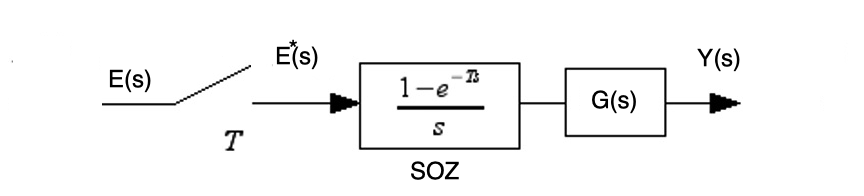

## Atividade 2 - Discretização da FT do modelo de ordem 1 

Seja o modelo G1 de ordem 1 discretizado com tempo de amostragem Ts:

Ts=0.02; % em segundos
G1d=c2d(G1,Ts)
figure
step(G1,G1d);
title('Fig.4 - Resposta ao degrau em malha aberta do modelo de ordem 1, contínuo e discreto')

2.1 Sabendo que a discretização mapeia um polo em $s=-a$ do plano s para o polo do plano z em $z=e^{-aT}$, ou seja, $G(z)=Z[{\frac{1}{s+a}]=\frac{z}{z-e^{-aT}$a  compare os polos de G1 e de G1d. Sugestão: use o comando pole na linha de comando do Matlab.

Resposta:

2.2 Sabendo que sistemas contínuos com resposta rápida têm polos no semiplano esquerdo longe da origem, onde estão os polos de sistemas discretos rápidos? (Dica: usar a expressão de 2.1).

Resposta:

## Atividade 3 - Avaliação do efeito do ganho no caso contínuo e no caso discreto 

Em malha fechada, o controlador discreto $C(z)$ é aplicado ao sistema contínuo dado pela FT $G(s)$. Um segurador de ordem zero (SOZ) mantém o sinal de controle U(s) aplicado constante entre instantes de amostragem $T$.

A funcão de transferência discreta de malha fechada para o diagrama abaixo é dada por $M(z)=\frac{C(z)G(z)}{1+C(z)G(z)}$, com $G(z)=Z\{SOZ*G(s)\}$.

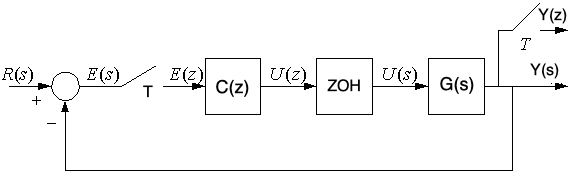

Nesta atividade se avalia a diferença do comportamento do sistema contínuo e discreto em malha fechada quando o ganho $K$varia, fazendo, $C(z)=K$. Para isso, usaremos o modelo estimado de ordem 2 (G2).

3.1 Use o comando rlocus e avalie o efeito do aumento do ganho $K$ nos polos do sistema contínuo em malha fechada, ou seja, o efeito de $K$ em $1+KG_2(s)=0$. Avalie estabilidade, sobreelevação, tempo de estabelecimento. 

Dica: vc pode dar o comando rlocus(G2) no workspace do Matlab, para melhor acesso ao dados do LR.

rlocus(G2)

Resposta:

3.2 Use o comando rlocus e avalie o efeito do aumento do ganho $K$ nos polos do sistema discreto em malha fechada, ou seja, o efeito de $K$ em $1+KG_{2d}(z)=0$.

G2d=c2d(G2,Ts);
rlocus(G2d)

Resposta:

3.3 Para que valores de $K$ o sistema discreto é estável?

Resposta:

3.4 Teste em malha fechada: aplique o controlador $C(s)=K $ no circuito RC e avalie a resposta transitória, fazendo referência ao lugar das raízes de $1+KG_{2d}(z)=0$. Use um ganho $K_{p1}$ que dê resposta sobreamortecida e um ganho $K_{p2}$ que dê uma resposta subamortecida.

[y,t]=arduino_coleta_rc(obj,0,3); % Zera saida
Kp1=0; % Escolher do LR de G2d
Kp2=0; % Escolher do LR de G2d
Ref=0; % Referencia (setpoint): escolher entre 50 e 200
[y1,~,t1] = arduino_controle_PI_rc(obj,Ref,Tempo, Kp1,0);
[y,t]=arduino_coleta_rc(obj,0,3); % Zera saida
[y2,~,t2] = arduino_controle_PI_rc(obj,Ref,Tempo, Kp2,0);
figure;
ss=sprintf('Fig.5: Resposta em malha fechada para o ganho Kp1=%2.1f e ganho Kp2=%2.1f',Kp1,Kp2);
plot(t1,y1,t2,y2);title(ss);
xlabel('Segundos');legend('K_{p1}','K_{p2}')
seta_saida_rc(obj,0);

Resposta: 

## Atividade 4 - Avaliação do efeito do tempo de amostragem

Os comandos abaixo geram 3 FTs discretas, cada uma com um tempo de amostragem diferente e crescente. Escolha estes tempos de amostragem de modo a ter respostas estáveis mas com sobreelevação crescente.

T1=[1 1 1]*Ts; % Escolher 3 valores crescentes de tempo de amostragem
gd1=c2d(G2,T1(1));
gd2=c2d(G2,T1(2));
gd3=c2d(G2,T1(3));
m1=feedback(gd1,1);
m2=feedback(gd2,1);
m3=feedback(gd3,1);
figure;
step(m1,m2,m3);title('Fig.6 - Resposta ao degrau em malha fechada para diferentes tempos de amostragem')
figure
pzmap(m1,m2,m3);
title('Fig.7 - Polos de malha fechada para as 3 FTs (observe as curvas de amortecimento constante)');grid
figure;
S1=stepinfo(m1);
S2=stepinfo(m2);
S3=stepinfo(m3);
UP=[S1.Overshoot S2.Overshoot S3.Overshoot ];
figure;bar(T1,UP, 0.3);
xlabel('Tempo de amostragem')
ylabel('Sobreelevação')
title('Figura 8. Relação entre tempo de amostragem e sobreelevação');

4.1 Qual o efeito do tempo de amostragem na sobreelevação?

Resposta:

4.2 Relacione as regiões dos polos no plano z com a sobreelevação, levando em consideração as curvas de amortecimento constante.

Resposta: